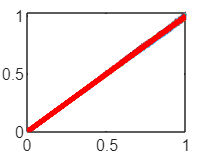

n = 10000;m = 100;
[w,t] = wiener(n,m);
kv = kvar(w);
plot(t,kv);
hold on
plot(t,t,'r','LineWidth',3);
hold off

max(max(abs(kv-t')))/(n*m)

ans = 3.8229e-08

max(max(abs(kv-t')))

ans = 0.0382

max(abs(kv(end,:)-t'))

ans =     0.9992    1.0062    1.0071    1.0036    1.0193    0.9783    1.0207    1.0252    0.9937    0.9832    1.0181    0.9850    0.9853    0.9953    0.9810    0.9920    1.0168    1.0172    1.0072    0.9851    0.9719    1.0145    1.0111    0.9987    1.0059    1.0105    1.0177    1.0092    0.9825    1.0145    1.0190    0.9921    0.9989    0.9993    1.0131    1.0017    1.0017    0.9941    0.9870    0.9985    0.9979    1.0157    1.0008    1.0017    0.9991    0.9875    0.9856    0.9832    1.0334    0.9976


**Polaritási formula**

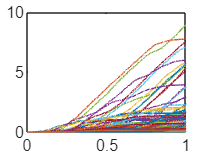

sv = kvar(stint(sin(w),w.^2));
plot(t,sv);

hv = stint(sin(w).^2,kvar(w.^2));
plot(t,hv);

max(max(abs(sv-hv))) %Mennyire teljesül a polaritási formula? 

ans = 4.3521e-14